clear; clc

dataDir = './CarData/TrainImages';
fileList = dir(fullfile(dataDir, '*.pgm'));
numFiles = length(fileList);

histograms = zeros(numFiles, 256);
labels = zeros(numFiles, 1);

for i = 1:numFiles
    img = imread(fullfile(dataDir, fileList(i).name));
    
    histogram = imhist(img, 256)';
    histograms(i, :) = histogram;
    
    if strncmp(fileList(i).name, 'pos', 3)
        labels(i) = 1; % Car
    else
        labels(i) = 0; % Not car
    end
end

save('histogram_data.mat', 'histograms', 'labels');

rng(0); 
shuffledIndices = randperm(numFiles);
numTrain = floor(2/3 * numFiles);

trainIndices = shuffledIndices(1:numTrain);
validationIndices = shuffledIndices(numTrain+1:end);

trainHistograms = histograms(trainIndices, :);
trainLabels = labels(trainIndices);
validationHistograms = histograms(validationIndices, :);
validationLabels = labels(validationIndices);

k = 5;
predictedLabels = zeros(length(validationIndices), 1);

for i = 1:length(validationIndices)
    validationHist = validationHistograms(i, :);
    
    sims = sum(min(trainHistograms, validationHist), 2);
    
    [~, neighborIndices] = maxk(sims, k);
    
    neighborLabels = trainLabels(neighborIndices);
    predictedLabels(i) = mode(neighborLabels);
end

accuracy = sum(predictedLabels == validationLabels) / length(validationLabels) * 100;
disp(['Accuracy: ', num2str(accuracy), '%']);

Accuracy: 65.4286%


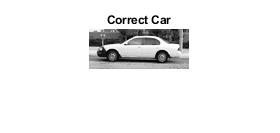


carCorrectlyLabeled = validationIndices(predictedLabels == 1 & validationLabels == 1);
notCarCorrectlyLabeled = validationIndices(predictedLabels == 0 & validationLabels == 0);
carIncorrectlyLabeled = validationIndices(predictedLabels == 1 & validationLabels == 0);
notCarIncorrectlyLabeled = validationIndices(predictedLabels == 0 & validationLabels == 1);

imshow(imread(fullfile(dataDir, fileList(carCorrectlyLabeled(1)).name))); title('Correct Car');

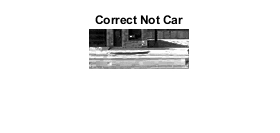

imshow(imread(fullfile(dataDir, fileList(notCarCorrectlyLabeled(1)).name))); title('Correct Not Car');

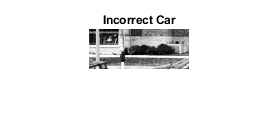

imshow(imread(fullfile(dataDir, fileList(carIncorrectlyLabeled(1)).name))); title('Incorrect Car');

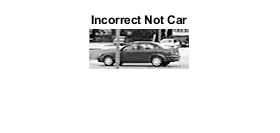

imshow(imread(fullfile(dataDir, fileList(notCarIncorrectlyLabeled(1)).name))); title('Incorrect Not Car');



% Part 3
hogHistograms = zeros(numFiles, 80); 
cellSize = [20, 20];
numBins = 8;

for i = 1:numFiles
    img = imread(fullfile(dataDir, fileList(i).name));
    
    hogFeatures = [];
    for r = 1:cellSize(1):size(img, 1)-cellSize(1)+1
        for c = 1:cellSize(2):size(img, 2)-cellSize(2)+1
            cellImg = img(r:r+cellSize(1)-1, c:c+cellSize(2)-1);
            
            %  gradients
            [gx, gy] = gradient(double(cellImg));
            magnitude = sqrt(gx.^2 + gy.^2);
            orientation = atan2(gy, gx);
            
            histogram = zeros(1, numBins);
            bin_edges = linspace(-pi, pi, numBins + 1);
            for b = 1:numBins
                bin_range = (orientation >= bin_edges(b)) & (orientation < bin_edges(b+1));
                histogram(b) = sum(magnitude(bin_range));
            end
            
            hogFeatures = [hogFeatures, histogram];
        end
    end
    
    hogHistograms(i, :) = hogFeatures;
end

trainHOGHistograms = hogHistograms(trainIndices, :);
validationHOGHistograms = hogHistograms(validationIndices, :);

k = 5;
predictedLabelsHOG = zeros(length(validationIndices), 1);

for i = 1:length(validationIndices)
    validationHOG = validationHOGHistograms(i, :);
    
    simsHog = sum(min(trainHOGHistograms, validationHOG));
    
    [~, neighborIndicesHOG] = maxk(simsHog, k);
    
    neighborLabelsHOG = trainLabels(neighborIndicesHOG);
    predictedLabelsHOG(i) = mode(neighborLabelsHOG);
end

accuracyHOG = sum(predictedLabelsHOG == validationLabels) / length(validationLabels) * 100;
disp(['Accuracy with HOG: ', num2str(accuracyHOG), '%']);

Accuracy with HOG: 70%


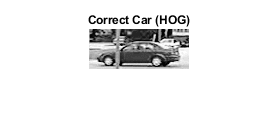


carCorrectlyLabeledHOG = validationIndices(predictedLabelsHOG == 1 & validationLabels == 1);
notCarCorrectlyLabeledHOG = validationIndices(predictedLabelsHOG == 0 & validationLabels == 0);
carIncorrectlyLabeledHOG = validationIndices(predictedLabelsHOG == 1 & validationLabels == 0);
notCarIncorrectlyLabeledHOG = validationIndices(predictedLabelsHOG == 0 & validationLabels == 1);

figure;

imshow(imread(fullfile(dataDir, fileList(carCorrectlyLabeledHOG(1)).name)));title('Correct Car (HOG)');

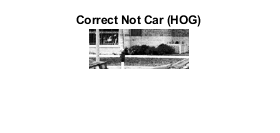


imshow(imread(fullfile(dataDir, fileList(notCarCorrectlyLabeledHOG(1)).name)));title('Correct Not Car (HOG)');

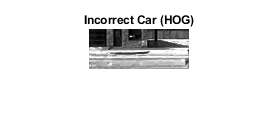


imshow(imread(fullfile(dataDir, fileList(carIncorrectlyLabeledHOG(1)).name)));title('Incorrect Car (HOG)');

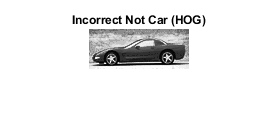


imshow(imread(fullfile(dataDir, fileList(notCarIncorrectlyLabeledHOG(1)).name)));title('Incorrect Not Car (HOG)');